# Electrostatic FEM of Gradient Structure 

## Import the Geometry

clear
clc
clf

set(0,'DefaultAxesFontSize',15,'defaultaxeslinewidth',2,...
'defaultlinelinewidth',5,'defaultpatchlinewidth',1.5)

Electrodep_model = createpde('electromagnetic','electrostatic');
%gmAir = multicuboid(40,40,40);
%gmAir.translate([6,5,-6]);
%pdegplot(gmAir)

Scaffold = importGeometry('Gradient structure full height.stl');
%pdegplot(Scaffold)

%gmModel = addCell(gmAir,Scaffold);

Electrodep_model.Geometry = Scaffold

Electrodep_model =   ElectromagneticModel with properties:

          AnalysisType: "electrostatic"
              Geometry: [1×1 DiscreteGeometry]
    MaterialProperties: []
               Sources: []
    BoundaryConditions: []
    VacuumPermittivity: []
                  Mesh: []


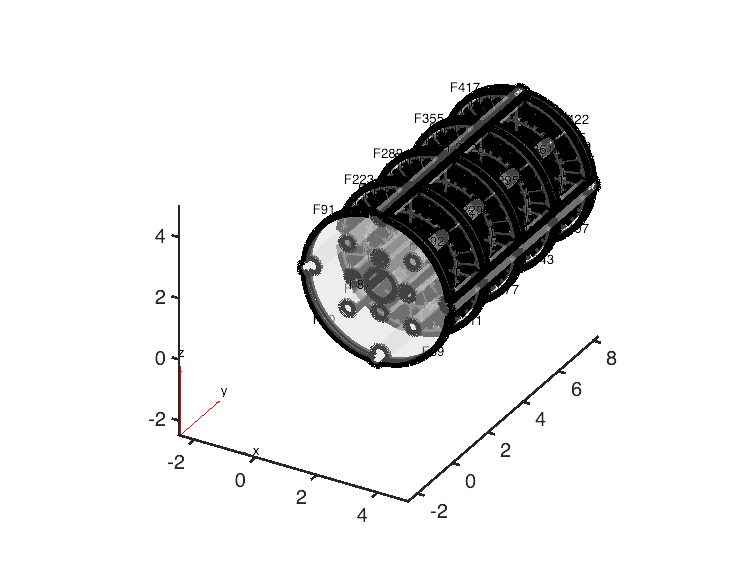


figure

%pdegplot(Electrodep_model,'EdgeLabels','on','FaceAlpha',0.1);

pdegplot(Electrodep_model,'FaceLabels','on','FaceAlpha',.3);

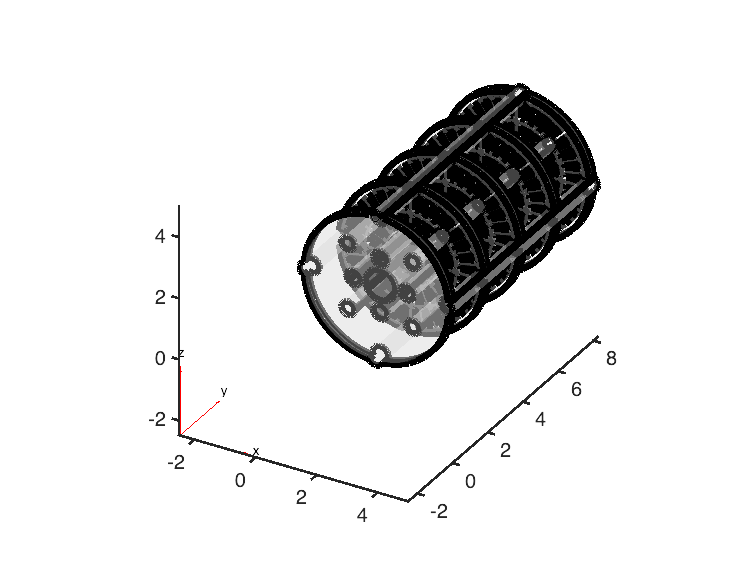


pdegplot(Electrodep_model,'CellLabels','on','FaceAlpha',.3);


%Splitting components 

%HEMA 110 um scaffold
HEM_Bottom_Faces = [8];


## Define Coefficients and Boundary Conditions

## Charge Density


%Scaffold
%electromagneticSource(Electrodep_model,"ChargeDensity",5E-10);

%% BC ITO
electromagneticBC(Electrodep_model,"Voltage",.075,"Face",HEM_Bottom_Faces)

ans =   ElectromagneticBCAssignment with properties:

    MagneticPotential: []
             RegionID: 8
           RegionType: 'Face'
           Vectorized: 'off'
              Voltage: 0.0750


%BC Scaffold
%electromagneticBC(Electrodep_model,"Voltage",0,"Face",3:6)
%BC Working
%BC Counter


## Material Properties   

%%Vacuum
Electrodep_model.VacuumPermeability = 1.2566370614E-6;
Electrodep_model.VacuumPermittivity = 8.8541878128E-12;

%%Culture Medium
%electromagneticProperties(Electrodep_model,"Cell",1,"RelativePermittivity",8);
% %%ITO
% electromagneticProperties(emagmodel,"RelativePermittivity",2.25, ...
%                                     "Face", ITO_Face)
% %%Electrodes
% electromagneticProperties(emagmodel,"RelativePermittivity",2.25, ...
%                                     "Face", ITO_Face)
%Scaffold
electromagneticProperties(Electrodep_model,"RelativePermittivity",4.74)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 1
    RelativePermittivity: 4.7400
    RelativePermeability: []
            Conductivity: []


**Specify Current Density**

## Create the Mesh

%generateMesh(Electrodep_model, 'Hmax',1);
generateMesh(Electrodep_model,'Hmax',.05);

## Solving the Model

emagmodel = Electrodep_model;
R = solve(emagmodel);

model = emagmodel;
%elemsBushing = findElements(model.Mesh,"Region","Cell",2);

pdeplot3D(model,"FlowData",[R.ElectricField.Ex ...
                                R.ElectricField.Ey ...
                                R.ElectricField.Ez],"FaceAlpha", .5)
title('Electric Field [V]')


pdeplot3D(model,"FlowData",[R.ElectricFluxDensity.Dx ...
                                R.ElectricFluxDensity.Dy ...
                                R.ElectricFluxDensity.Dz],"FaceAlpha", .5)
title('Flux Density')



pdeplot3D(model,"ColorMapData",R.ElectricPotential)
title('Electric Potential [V]')

Emag = sqrt(R.ElectricField.Ex.^2 + ...
            R.ElectricField.Ey.^2 + ...
            R.ElectricField.Ez.^2);
pdeplot3D(model, ...
          "ColorMapData",Emag);
